# Auto-generated by Image Acquisition Explorer

Generated in MATLAB R2024a on 2026-05-11 17:13:30

## Connect to Device

Create connection to the device using the specified adaptor with the specified format.

v = videoinput("gentl", 1, "Mono8");

## Configure Device-Specific Properties

Configure properties that are specific to this device.

src = getselectedsource(v);
src.ExpectedGrayValue = 120;

## Capture Image

Capture a single frame.

snapshot2 = getsnapshot(v);

## View Snapshot

Display the captured image.

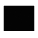

f = figure;
ax = axes(f);
imshow(snapshot2, "Parent", ax);

## Clean Up

Delete the videoinput object and clear variables from the workspace.

delete(v)
clear src v